clear
close all
x=-30:0.0001:30;

Set gaussian sigma parameter (standard deviation of the gaussian)

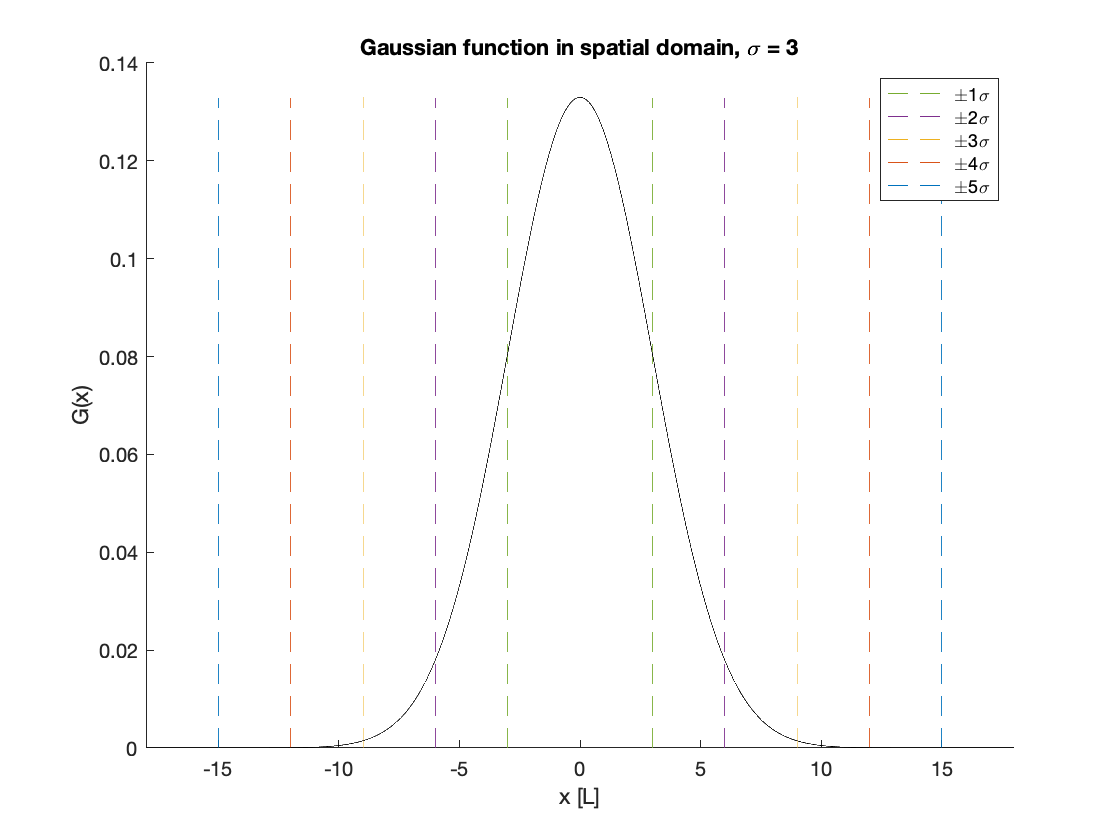

sigma=3;
   
%Define the gaussian function
G=(1./(sqrt(2*pi).*sigma)).*exp(-(x.^2)./(2.*sigma.^2));

%Find sigma intervals
sigmax = sort(sigma.*[-5:-1,1:5]'*[1 1]); % values at +-1sigma, +-2sigma, etc.
sigmay = repmat([0 max(G)],10,1); %yrange to plot lines at sigmax values

%Plot gaussian in spatial domain
figure(1);clf
c=get(gca,'colororder');
cnew=[c(1:5,:);flipud(c(1:5,:))];
set(gca,'ColorOrder',cnew,'NextPlot', 'replacechildren')
px = plot(sigmax',sigmay','--');hold on
plot(x,G,'k');
ylabel('G(x)');xlabel('x [L]')
xlim(6.*sigma.*[-1 1])
title(['Gaussian function in spatial domain, \sigma = ',num2str(sigma)]);
legend(px(6:10),{'\pm1\sigma' '\pm2\sigma' '\pm3\sigma' '\pm4\sigma' '\pm5\sigma' })

Note that $1\sigma =68\ldotp 27%$, $2\sigma =95\ldotp 45%$, $3\sigma =99\ldotp 73%$ of data.

Fourier transformed Gaussian:

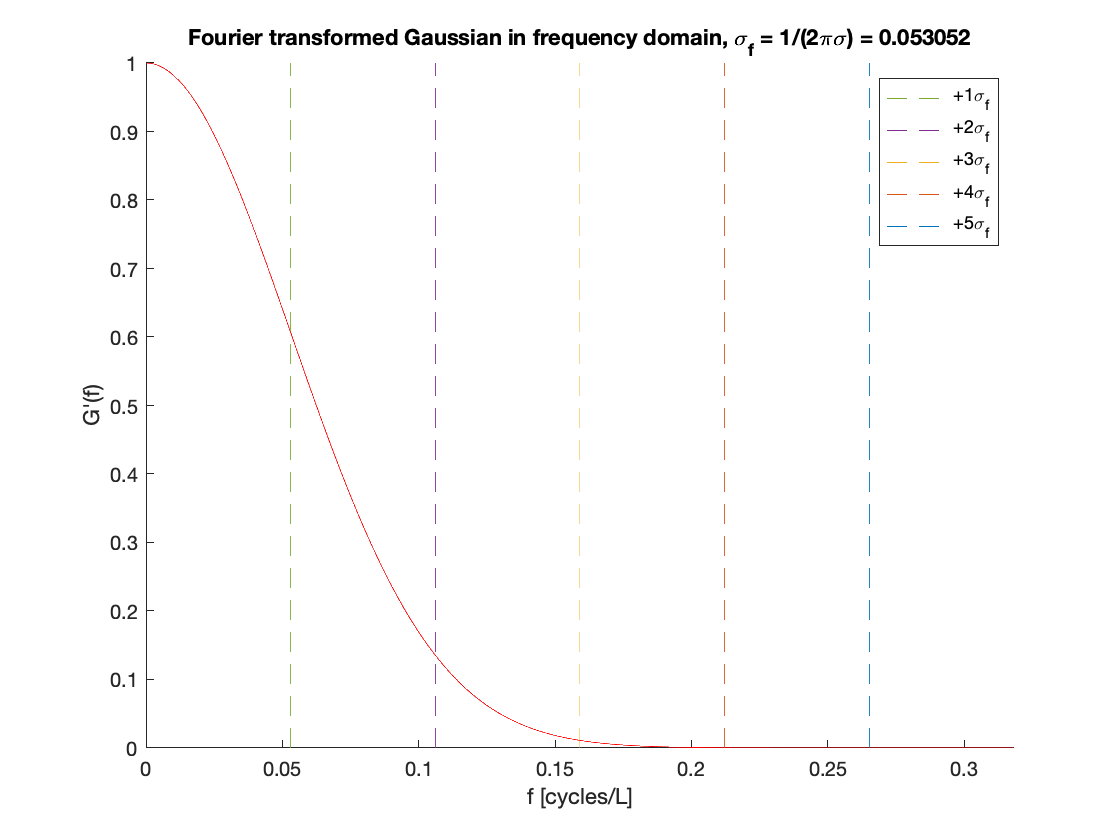

% The standard deviation of the fourier transformed Gaussian is sigma_f,
% which is related to sigma by:
sigma_f=1./(2.*pi.*sigma);

%In wavelengths, this is:
sigma_l=1./sigma_f;

f=x;
lambda=1./f;

% Define the fourier transformed Gaussian function:
G_f=exp(-(f.^2)./(2.*sigma_f.^2));

%Find sigma_f (frequency) and sigma_l (wavelength) intervals
sigma_fx = sigma_f.*[1:5]'*[1 1];
sigma_fy = repmat([0 max(G_f)],5,1);

sigma_lx = 1./sigma_fx;
sigma_ly = sigma_fy;

%Plot fourier transform in frequency space
figure(2);clf
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
pf = plot(sigma_fx',sigma_fy','--');hold on    
plot(f,G_f,'r');ylabel('G''(f)');xlabel('f [cycles/L]')
xlim([0 6.*sigma_f])
title(['Fourier transformed Gaussian in frequency domain, \sigma_f = 1/(2\pi\sigma) = ',num2str(sigma_f)]);
legend({'+1\sigma_f' '+2\sigma_f' '+3\sigma_f' '+4\sigma_f' '+5\sigma_f' })

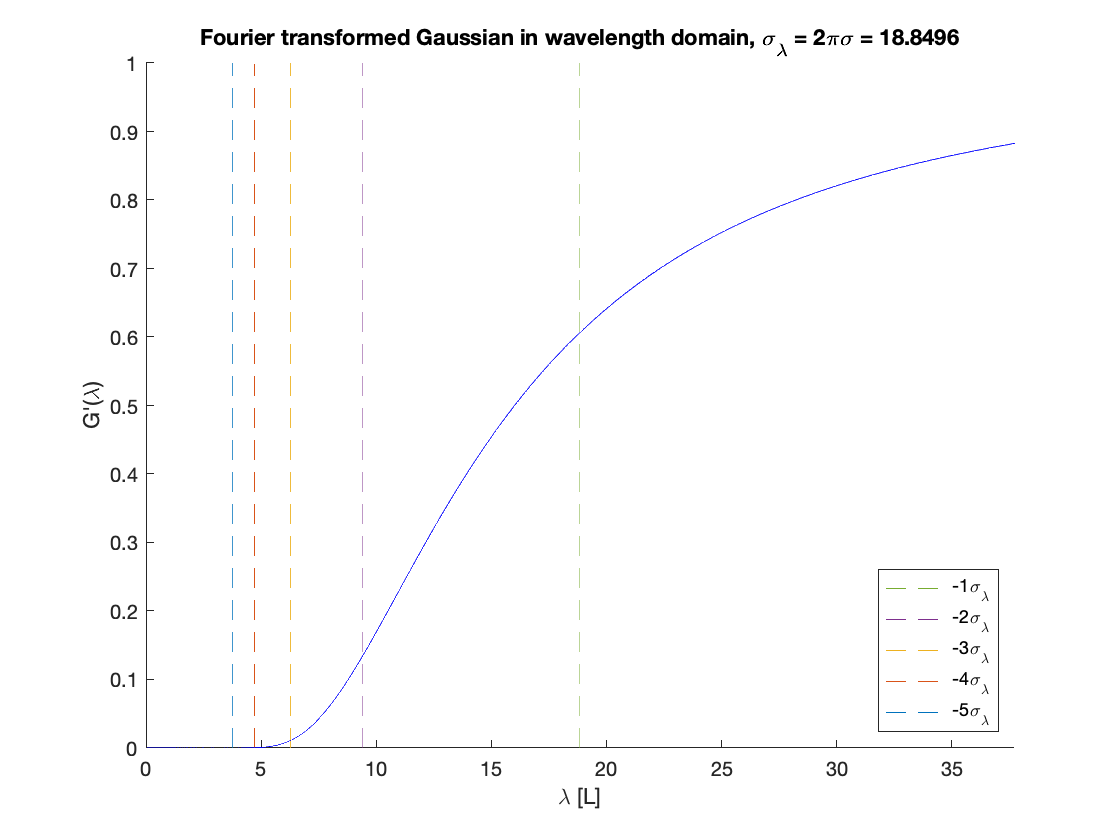


%Plot against wavelength
figure(3);clf
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
plot(sigma_lx',sigma_ly','--');hold on        
plot(lambda,G_f,'b');ylabel('G''(\lambda)');xlabel('\lambda [L]')
xlim([0 2.*sigma_l])
title(['Fourier transformed Gaussian in wavelength domain, \sigma_\lambda = 2\pi\sigma = ',num2str(sigma_l)]);
legend({'-1\sigma_\lambda' '-2\sigma_\lambda' '-3\sigma_\lambda' '-4\sigma_\lambda' '-5\sigma_\lambda'}, 'location','southeast')

Gaussian frequency response $\hat{G} \left(f\right)$ is essentially zero by $3\sigma_f$.

Gaussian spatial standard deviation $\sigma$ and frequency response standard deviation $\sigma_f$ are related by: $\sigma_f =\frac{1}{2\pi \sigma }$. 

Spatial wavelength $\lambda =\frac{1}{f}$ where $f$ is frequency in $\frac{\textrm{cycles}}{\left\lbrack L\right\rbrack }$. 

Therefore, the $3\sigma_{\lambda \;}$wavelength by which amplitude is nearly fully attenuated is $\lambda_0 =\frac{2\pi \sigma }{3}$.

disp(['sigma = ',num2str(sigma)])

sigma = 3


lambda0 = 2*pi*sigma/3

lambda0 = 6.2832

Gatt=exp(-((1/lambda0).^2)./(2.*sigma_f.^2));
disp(['G(lambda0) = ',num2str(Gatt)]);

G(lambda0) = 0.011109


Inverse: to fully attenuate all wavelengths $<\lambda {\;}_0$, use $\sigma_f ~\frac{f_0 }{3}=\frac{1}{3\lambda_0 }\to \sigma =\frac{3\lambda_0 }{2\pi }$. 

lambda0 = 2.4%Set a minimum wavelength to pass through filter

lambda0 = 2.4000

sigma=3*lambda0/(2*pi)

sigma = 1.1459

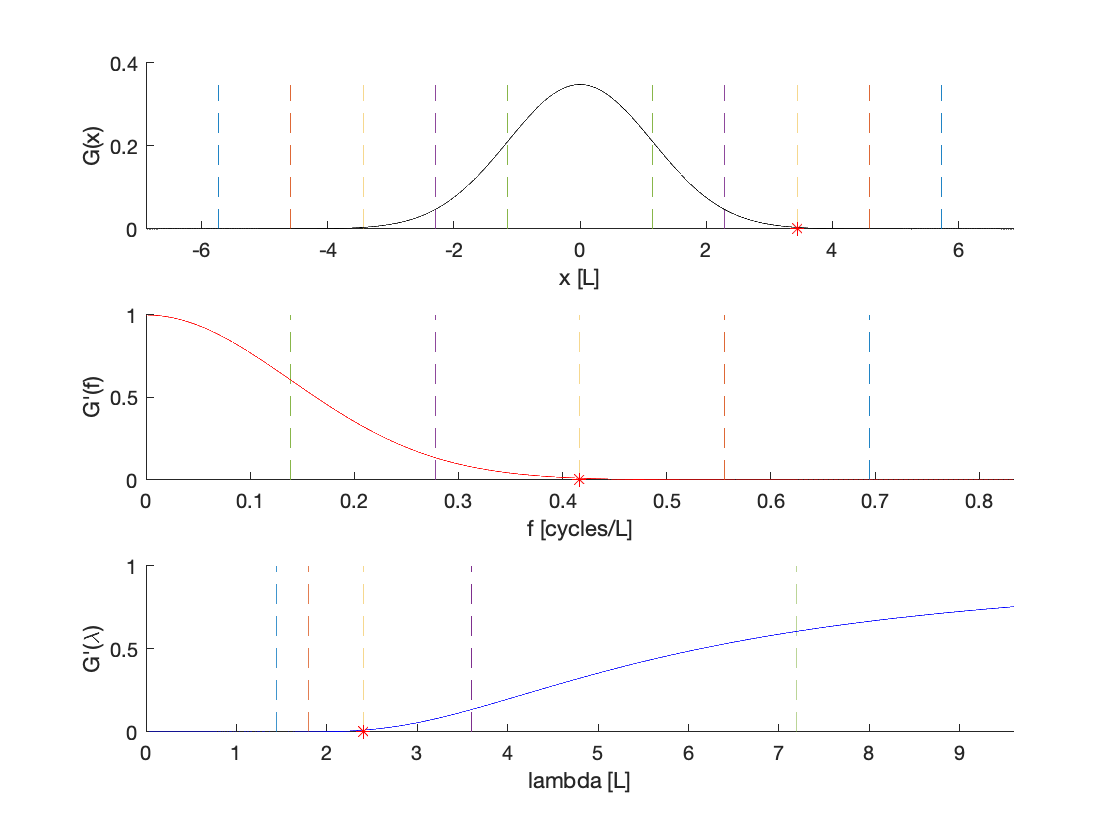


G=(1./(sqrt(2*pi).*sigma)).*exp(-(x.^2)./(2.*sigma.^2));
sigma_f=1./(2.*pi.*sigma);
sigma_l=1./sigma_f;
G_f=exp(-(f.^2)./(2.*sigma_f.^2));

%Find sigma and sigma_f intervals
sigmax = sort(sigma.*[-5:-1,1:5]'*[1 1]);
sigmay = repmat([0 max(G)],10,1);
sigma_fx = sigma_f.*[1:5]'*[1 1];
sigma_fy = repmat([0 max(G_f)],5,1);
sigma_lx = 1./sigma_fx;
sigma_ly = repmat([0 max(G_f)],5,1);


%PLOTS
figure(4);clf
subplot(3,1,1)
c=get(gca,'colororder');
cnew=[c(1:5,:);flipud(c(1:5,:))];
set(gca,'ColorOrder',cnew,'NextPlot', 'replacechildren')
plot(sigmax',sigmay','--');hold on
plot(x,G,'k');
plot(3*sigma,0,'r*')
ylabel('G(x)');xlabel('x [L]')
xlim(6.*sigma.*[-1 1])

subplot(3,1,2)
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
plot(sigma_fx',sigma_fy','--');hold on    
plot(f,G_f,'r');ylabel('G''(f)');xlabel('f [cycles/L]')
plot(3*sigma_f,0,'r*')
xlim([0 6.*sigma_f])

subplot(3,1,3)
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
plot(sigma_lx',sigma_ly','--');hold on        
plot(lambda,G_f,'b');ylabel('G''(\lambda)');xlabel('lambda [L]')
plot(lambda0,0,'r*')
xlim([0 4.*lambda0])